close all
clear all
clc

## Select an image

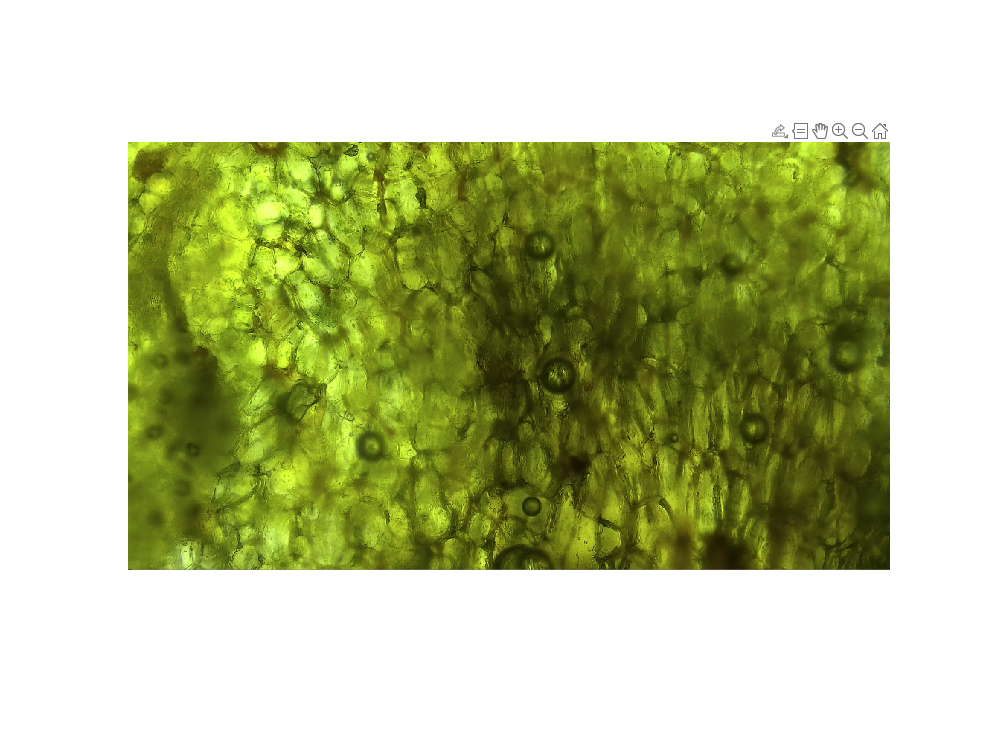

S = struct('filename',{},'pathname',{},'I',[]);

count = 4; % number of images that you are going to process 
crop = 1; % input 1 if you will crop and 0 if will not need to crop

for i = 1:count
[filename,pathname] = uigetfile({'*.*';'*.bmp';'*.tif';'*.jpg';'*.png';...
    '*.jpeg';'*.gif'},'Pick an Image');
S(i).filename = filename;
S(i).pathname = pathname;
if crop == 0
S(i).I = imread([pathname,filename]);
  elseif crop == 1
    S(i).I = imread([pathname,filename]);
    S(i).cI = imcrop(S(i).I);
end 

end

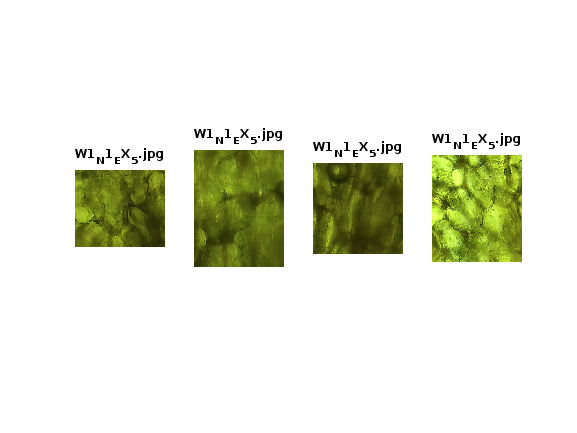

if crop == 1
    figure(23)
    for c = 1:count
    subplot(1,count,c)
    imshow(S(c).cI), title(S(c).filename)
    end
end

%I = imread([pathname,filename]);

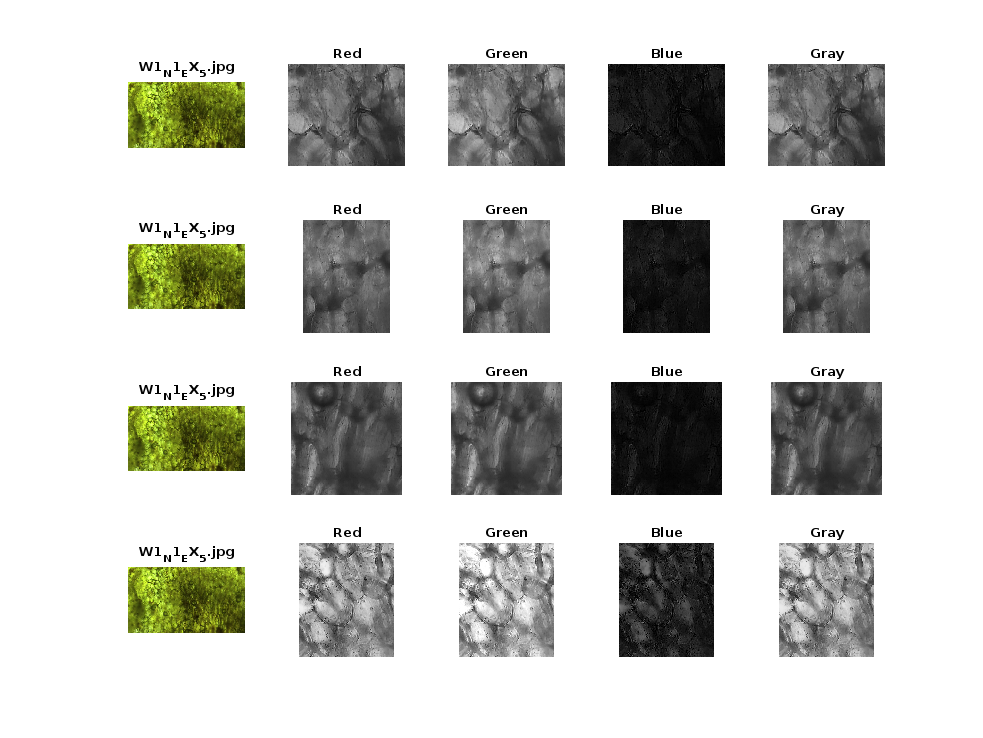

for i = 1:count 
    if crop == 0
        S(i).r = S(i).I(:, :, 1);
        S(i).g = S(i).I(:, :, 2);
        S(i).b = S(i).I(:, :, 3);
        S(i).gI = rgb2gray(S(i).I);
    elseif crop == 1
        S(i).r = S(i).cI(:, :, 1);
        S(i).g = S(i).cI(:, :, 2);
        S(i).b = S(i).cI(:, :, 3);
        S(i).gI = rgb2gray(S(i).cI);
    end 
end
 figure(1)
 i = 1;
for k = 1:count
    subplot(count,5,i)
    i= i+1;
    imshow(S(k).I), title(S(k).filename)
    subplot(count,5,i)
    i= i+1;
    imshow(S(k).r), title('Red')
    subplot(count,5,i)
    i = i+1;
    imshow(S(k).g), title('Green')
    subplot(count,5,i)
    i = i+1;
    imshow(S(k).b), title('Blue')
   subplot(count,5,i)
    i = i+1;
    imshow(S(k).gI), title('Gray')
end

% figure(2)
% subplot(2,4,1)
% imshow(r);
% subplot(2,4,2)
% imshow(g);
% subplot(2,4,3)
% imshow(b);
% subplot(1,4,4)
% imshow(gI);
% title("Gray")
% subplot(2,4,5)
% image(r);
% colorbar
% subplot(2,4,6)
% image(g);
% subplot(2,4,7)
% image(b);
% subplot(2,4,8)
% image(I);

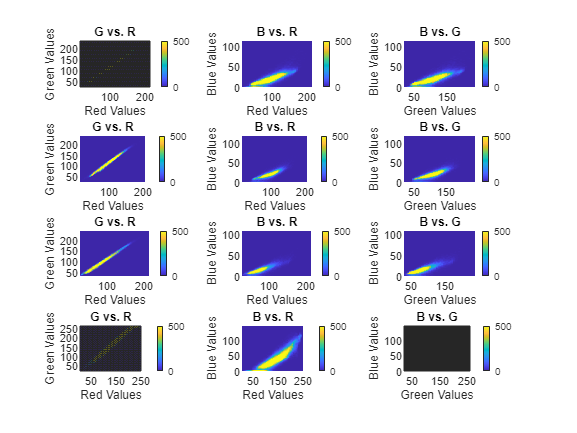


figure(2)
k = 1;
for n = 1:count 
subplot(count,3,k)
k = k+1;
histogram2(S(n).r, S(n).g, 'DisplayStyle',"tile", 'ShowEmptyBins','on')
colorbar
xlabel('Red Values')
ylabel('Green Values')
title('G vs. R')
ax = gca;
ax.CLim = [0 500];

subplot(count,3,k)
k = k+1;
histogram2(S(n).r, S(n).b, 'DisplayStyle',"tile", 'ShowEmptyBins','on')
colorbar
xlabel('Red Values')
ylabel('Blue Values')
title('B vs. R')
ax = gca;
ax.CLim = [0 500];

subplot(count,3,k)
k = k+1;
histogram2(S(n).g, S(n).b, 'DisplayStyle',"tile", 'ShowEmptyBins','on')
colorbar
xlabel('Green Values')
ylabel('Blue Values')
title('B vs. G')
ax = gca;
ax.CLim = [0 500];

% histogram(r, 'BinMethod','integers', 'FaceColor', 'r',...
%     "EdgeAlpha",0, 'FaceAlpha',1)
% hold on
% histogram(g, 'BinMethod','integers', 'FaceColor', 'g',...
%     "EdgeAlpha",0, 'FaceAlpha',0.7)
% histogram(b, 'BinMethod','integers', 'FaceColor', 'b',...
%     "EdgeAlpha",0, 'FaceAlpha',0.7)
% hold off
% xlabel('RGB Values')
% ylabel('Freq')
end

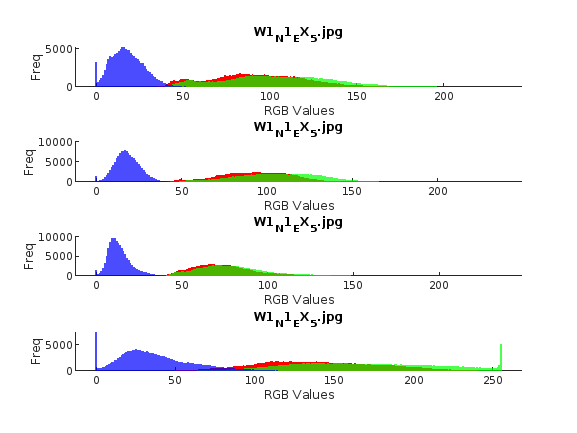

k = 1;
figure(3)
for n = 1:count
subplot(count,1,k)
hold on
histogram(S(n).r, 'BinMethod','integers', 'FaceColor', 'r',...
    "EdgeAlpha",0, 'FaceAlpha',1)
hold on
histogram(S(n).g, 'BinMethod','integers', 'FaceColor', 'g',...
    "EdgeAlpha",0, 'FaceAlpha',0.7)
histogram(S(n).b, 'BinMethod','integers', 'FaceColor', 'b',...
    "EdgeAlpha",0, 'FaceAlpha',0.7)
hold off
xlabel('RGB Values')
ylabel('Freq')
title(S(n).filename)
hold off
k = k+1;
end

% figure(4)
% imhist(S(1).g(:,:,1))

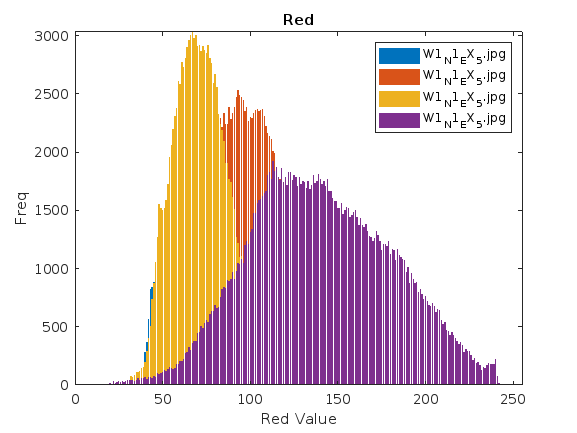

% this will plot 3 diffrent samples 
for n = 1:count
    [S(n).yred, S(n).Xr] = imhist(S(n).r);
    [S(n).ygre, S(n).Xg] = imhist(S(n).g);
    [S(n).yblu, S(n).Xb] = imhist(S(n).b);
end

figure(4)
for j = 1:count
    bar(S(j).Xr, S(j).yred)
    hold on
    if j == count
       legend(S(1:count).filename)   
    end
end
title('Red')
xlabel('Red Value')
ylabel('Freq')
%colorbar
axis([0 255 0 inf])
hold off

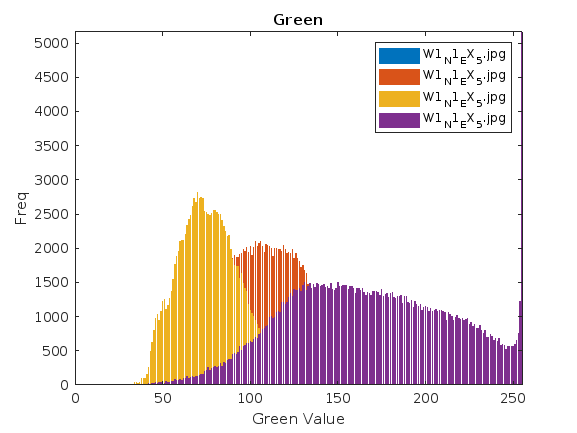


figure(5)
for j = 1:count
    bar(S(j).Xg, S(j).ygre)
    hold on
    if j == count
       legend(S(1:count).filename)   
    end
end
title('Green')
xlabel('Green Value')
ylabel('Freq')
%colorbar
axis([0 255 0 inf])
hold off

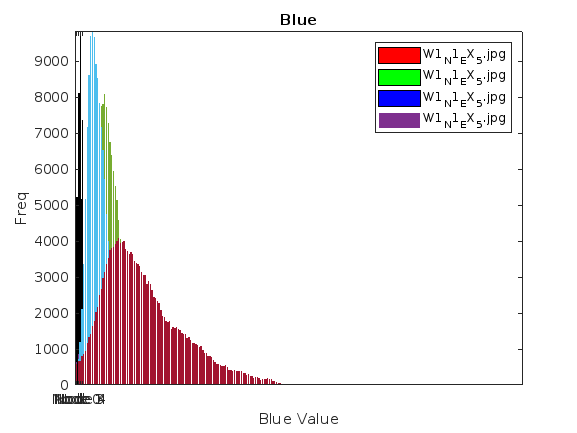


figure(6)
for j = 1:count
    bar(S(j).Xb, S(j).yblu)
    hold on
    if j == count
       legend(S(1:count).filename)   
    end
end
title('Blue')
xlabel('Blue Value')
ylabel('Freq')
%colorbar
axis([0 255 0 inf])
hold off

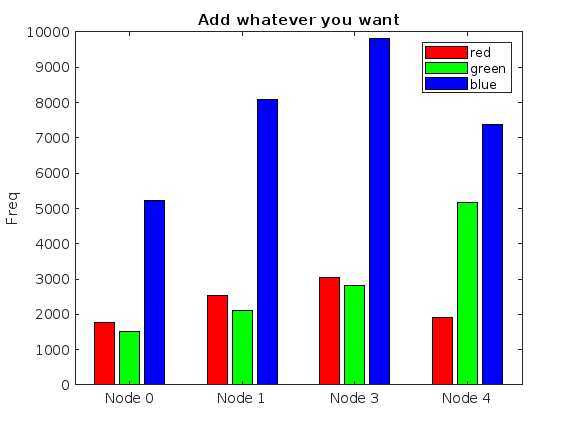


for i = 1:count
    s(i).maxR = max(S(i).yred);
    s(i).maxG = max(S(i).ygre);
    s(i).maxB = max(S(i).yblu);
end

%bary = [s(:).meanR; s(:).meanG; s(:).meanB];
bary = [s(1).maxR s(1).maxG s(1).maxB; s(2).maxR s(2).maxG s(2).maxB;...
    s(3).maxR s(3).maxG s(3).maxB; s(4).maxR s(4).maxG s(4).maxB];
barx = {'image 1', 'image 2', 'image 3'};
h = bar(bary,'grouped');
h(1).FaceColor = [1 0 0];
h(2).FaceColor = [0 1 0];
h(3).FaceColor = [0 0 1];
hold on 
%xCnt = (get(h(1),'XData') + cell2mat(get(h,'XOffset'))).'; 
% for i = 1:4
%     x(:,i) = h(i).XEndPoints;
% end
           % Red error  B error  G error
% RGB_err = [10 20 50; 25 22 23; 100 50 80]; 
% errorbar(x',bary,RGB_err,'k','linestyle','none')
xticklabels({'Node 0', 'Node 1', 'Node 3', 'Node 4'})
legend({'red','green','blue'})
ylabel('Freq')
title('Add whatever you want')


% imhist(S(1).r)
% hold on 
% imhist(S(2).r)
% imhist(S(3).r)
% hold off
% legend(S(1).filename, S(2).filename, S(3).filename)

figure(7)
i = 1;
for k = 1:count
    subplot(count,1,i)
    i = i+1;
    contour(double(S(k).gI)),title(S(k).filename)
    colormap jet
end
% xlabel('B')
% ylabel('G')
% zlabel('R')
% red = I;
% red(:,:,2) = 0;
% red(:,:,3) = 0;
% image(red)

## Segmentation

figure(7)
k = 1;
for i = 1:count
if crop == 0
lab_I = rgb2lab(S(i).I);
ab = lab_I(:,:,2:3);
ab = im2single(ab);
n = 3;
pixel_lab = imsegkmeans(ab,n,'NumAttempts',3);
subplot(count,4,k)
imshow(pixel_lab,[]), title(S(i).filename)
k= k+1;
%Cluster 1
S(k-1).mask = pixel_lab==1;
S(k-1).cluster = S(i).I.*uint8(S(k-1).mask);
subplot(count,4,k)
imshow(S(k-1).cluster)
k = k+1;

%cluster 2
S(k-1).mask = pixel_lab==2;
S(k-1).cluster = S(i).I.*uint8(S(k-1).mask);
subplot(count,4,k)
imshow(S(k-1).cluster)
k = k+1;
%cluster 3
S(k-1).mask = pixel_lab==3;
S(k-1).cluster = S(i).I.*uint8(S(k-1).mask);
subplot(count,4,k)
imshow(S(k-1).cluster)
k = k+1;
elseif crop == 1
    lab_I = rgb2lab(S(i).cI);
    ab = lab_I(:,:,2:3);
    ab = im2single(ab);
    n = 3;
    pixel_lab = imsegkmeans(ab,n,'NumAttempts',3);
    subplot(count,4,k)
    imshow(pixel_lab,[]), title(S(i).filename)
    k= k+1;
    %Cluster 1
    S(k-1).mask = pixel_lab==1;
    S(k-1).cluster = S(i).cI.*uint8(S(k-1).mask);
    subplot(count,4,k)
    imshow(S(k-1).cluster)
    k = k+1;

    %cluster 2
    S(k-1).mask = pixel_lab==2;
    S(k-1).cluster = S(i).cI.*uint8(S(k-1).mask);
    subplot(count,4,k)
    imshow(S(k-1).cluster)
    k = k+1;
    %cluster 3
    S(k-1).mask = pixel_lab==3;
    S(k-1).cluster = S(i).cI.*uint8(S(k-1).mask);
    subplot(count,4,k)
    imshow(S(k-1).cluster)
    k = k+1;
end
end


## Error

% Standard deviation 
R_SD = std(S(:).meanR);
G_SD = std(S(:).meanG);
B_SD = std(S(:).meanB);

% lab_I = rgb2lab(S(1).I);
% ab = lab_I(:,:,2:3);
% ab = im2single(ab);
% nColors = 8;
% pixel_lables = imsegkmeans(ab, nColors, "NumAttempts",3);
% imshow(pixel_lables, [])
% for i=1:nColors
%     s(i).mask = pixel_lables==i;
%     s(i).cluster=S(1).I.*uint8(s(i).mask);
% end
% for k=1:nColors
%     subplot(1,nColors,k)
%     imshow(s(k).cluster),title(k)
% end

## Save

% savename = 'week2_EX1N2_3.1.mat';
% save('savename','-append')